clear all
close all 
mask_struct = open("image_data_mask.mat");
image_struct = open("image_data.mat");


mask_img = mask_struct.out.image_data_masked;
whole_img =  mask_struct.out.image_data;

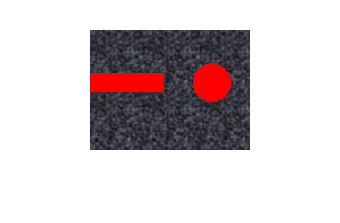

figure(1);
for i = 1:101
    imshow(whole_img(:,:,:,i));  % Added the closing parenthesis
    pause(0.2);  % Pauses for 0.2 seconds before showing the next frame
end

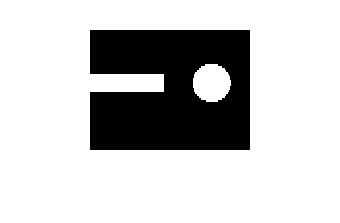

figure(2)
for i = 1:101
    imshow(mask_img(:,:,i));  % Added the closing parenthesis
    pause(0.2);  % Pauses for 0.2 seconds before showing the next frame
end

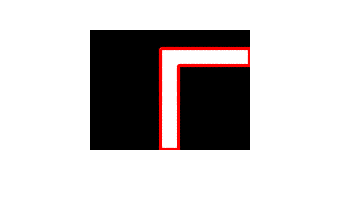

% Assuming BW is your binary mask showing the red line
% Use bwboundaries to find the contours of the white regions
BW = mask_img(:,:,30);
boundaries = bwboundaries(BW);

% Visualize the original image with contours
imshow(BW);
hold on;

% Loop through each boundary and plot it
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % plot y, x coordinates
end
hold off;

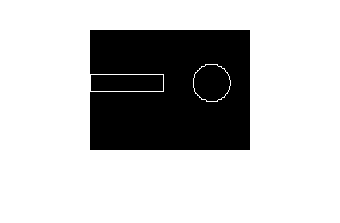

% Assuming BW is your binary mask showing the red line
% Use bwboundaries to find the contours of the white regions
figure(2)
for i = 5:101
    BW = mask_img(:,:,i);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for i = 1:size(boundary, 1)
            black_image(boundary(i,1), boundary(i,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Display the black image with white boundaries
    imshow(black_image);
    pause(0.2)
end

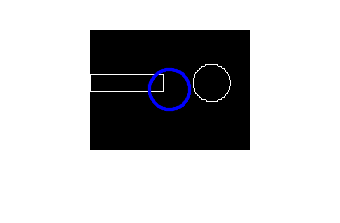

figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for j = 1:size(boundary, 1)
            black_image(boundary(j,1), boundary(j,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Display the black image with white boundaries
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue outline with width of 2
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end

figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for j = 1:size(boundary, 1)
            black_image(boundary(j,1), boundary(j,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Display the black image with white boundaries
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue outline with width of 2

    % Check for intersections and plot red points at intersections
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the boundary (white pixel in the original image)
        if BW(cy, cx) == 255  % 255 indicates the boundary point (white)
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point (intersection)
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end

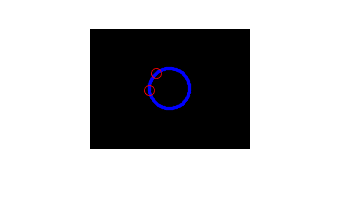

figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue circle
    
    % Find intersections
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the contour
        if any(ismember(contour_points, [cy, cx], 'rows'))  % Check if [cx, cy] is in contour_points
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end

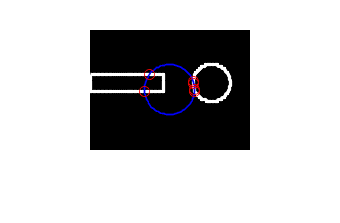

figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 25;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the contours in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2);  % Plot y, x coordinates in white
    end

    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 1);  % Blue circle
    
    % Find intersections and mark them as red
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the contour
        if any(ismember(contour_points, [cy, cx], 'rows'))  % Check if [cx, cy] is in contour_points
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end

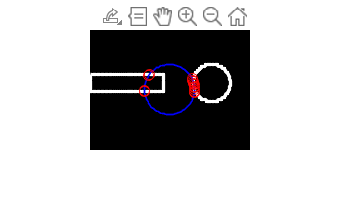

figure(4)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 25;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the contours in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2);  % Plot y, x coordinates in white
    end

    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 1);  % Blue circle
    
    % Find intersections using distance-based checking and mark them as red
    intersection_threshold = 1;  % Threshold for distance to detect intersections (in pixels)
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is within the threshold distance of any contour point
        distances = sqrt((contour_points(:,1) - cy).^2 + (contour_points(:,2) - cx).^2);
        if any(distances <= intersection_threshold)  % Check if any distance is below threshold
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end